# Supplementary information: Experimental progress towards single-pass STEM-EMCD on a zone axis using a patterned aperture

Thomas Thersleff, Linus Schönström, Cheuk-Wai Tai, Roman Adam, Daniel E. Bürgler, Claus M. Schneider, Shunsuke Muto, and Jan Rusz

## Introduction to this script and the supplementary information

This document guides the reader through all of the processing steps necessary to reach the conclusions drawn in the paper it supplements.  It was written using the Matlab Live Script utility in version R2018b.  The purpose is to provide the entire processing workflow necessary to generate the figures.  The functions used in this script are provided alongside the data and are available through the Zenodo website at the following URL or using the digital object identifier listed below:

[https://zenodo.org/record/3361582](https://zenodo.org/record/3361582)

10.5281/zenodo.3361582

### Description of the files

There are four files included with this script.  All are the raw data as captured in the TEM.  The two data files are saved in Gatan's proprietary `.dm4` format, while the two timestamp files (which allow for synchronizing the data frame to the probe position) are saved in Gatan's proprietary `.gtg` tag structure format.  The timestamp files are used to arrange the data into a 4D datacube, which subsequently allows for the STEM-DP and 4D-EELS datasets to be correlated through their common spatial dimensions.

- `EELS4D_Movie.dm4:   I`mage stack of all of the 2D EELS frames that were captured from the Ultrascan camera running in "view" mode using the hook-up script written by Linus Schönström and a modification of the frame recorder written by Vincent Hou (see the manuscript for details).

- `DP_Movie.dm4:   `Image stack of all of the CBED frames that were captured from the Orius camera running in "view" mode using the hook-up script written by Linus Schönström and a modification of the frame recorder written by Vincent Hou (see the manuscript for details).

- `STEMDP_TimeStamps.gtg`: Collection of time stamps for the STEM-DP experiment.  It goes along with the file `DP_Movie.dm4`.

- `EELS4D_TimeStamps.gtg`:    Collection of time stamps for the 4D EELS experiment.  It goes along with the file `EELS4D_Movie.dm4`.

### Dependencies

The use of this script relies on a number of third party software packages.  First and foremost, both a recent version of Matlab as well as the optimization toolbox is required.  These are commercial packages that must be purchased from [The Mathworks, Inc](http://www.mathworks.com/store). This script was written in version R2018b.

The raw data were recorded and are thus provided in a proprietary format developed by [Gatan, Inc](http://www.gatan.com/).  To import them into Matlab, I use Andreas Korinek's [dmread.m](https://se.mathworks.com/matlabcentral/fileexchange/45933-gatan-digital-micrograph-file-reader) script, which, at the time of writing, can be downloaded from the Matlab file exchange.  I have included it in the package for this work along with a small bug-fix that was necessary on my computer.

The divergent colormaps come from a Matlab implentation [BrewerMap](https://github.com/DrosteEffect/BrewerMap), which is based off of the colormaps developed by Cynthia Brewer ([http://colorbrewer.org](http://colorbrewer.org)).  I provide a copy of this library with this script.

For false-color sequential colormap (with the exception of grayscale), I use the MatPlotLib 2.0 default colormap "inferno," as implemented in Matlab in the [Colormaps-from-MatPlotLib2.0](https://github.com/DrosteEffect/Colormaps-from-MatPlotLib2.0) library.  An unmodified copy of this library is included with this script.

Sub-channel shifts in `applyISOmap.m` use version 1.1.0.0 of the package "[Efficient subpixel image registration by cross-correlation](http://www.mathworks.com/matlabcentral/fileexchange/18401-efficient-subpixel-image-registration-by-cross-correlation)" by Manuel Guizar et. al.  This code is based off of the citation below and is provided along with this script.

    Manuel Guizar-Sicairos, Samuel T. Thurman, and James R. Fienup, "Efficient subpixel image registration algorithms," Opt. Lett. 33, 156-158 (2008).

### To run this script

- Create a new folder and copy the data (`.dm4` and `.gtg` files) into it.

- Copy this script into the base folder.

- Copy all of the dependencies into their respective subfolders.

- Open up Matlab and navigate to this folder within the developer environment

- Run this script, selecting the appropriate `.dm4` files when prompted.

## Import the EELS data

If the dependencies are in separate folders within the rootfolder where you placed the data, you can add them by executing the following code from within the Matlab command line once:

### Generate the axis vectors in real space and reciprocal space

dq = 12.37/21.4; %mrad.  Sample of reciprocal space
qx = ((0:255) - 128) .* dq; %mrad.  Reciprocal space vector for STEM-DP dataset
x = ((0:79) - 40) .* 6.25; %nm.  Real space vector

% The vector qy will be used for the 2D EELS frames.  There are 32 channels
% and the spacing between them is about 2.2 mrad.  We center it at zero in
% the middle of the vector
dqy = 2.2 %mrad

dqy = 2.2000

qy = ((1:32) - (32/2)) .* dqy;

### Load the 4D EELS dataset

tg = dmread('EELS4D_Movie.dm4');
A = reshape(tg.ImageList.Unnamed1.ImageData.Data.Value, ...
            tg.ImageList.Unnamed1.ImageData.Dimensions.Unnamed0.Value, ...
            tg.ImageList.Unnamed1.ImageData.Dimensions.Unnamed1.Value, ...
            tg.ImageList.Unnamed1.ImageData.Dimensions.Unnamed2.Value);
A = double(A);
size(A)

ans =         2048          32        8000


clear tg;

### Load the tag file with time stamps

The function `getDiffImage` is used to import only the timestamps.  We will not construct the 4D EELS datacube just yet, as we will perform all of the EELS pretreatment procedures on the raw data first.  Thus, we pass a dummy variable (~) to the first output.

% When prompted, choose the file "EELS4D_Movie.dm4"
[~, ts] = getDiffImage('EELS4D_TimeStamps.gtg');

Found and removed 1 bad pixel timestamp(s)
ESI was paused 0 time(s).  Expecting 1 DP stack(s)


### Get the "good frames" (i.e. 2D EELS frames that were acquired with a well-defined pixel position)

This also removes the frames acquired while the probe was not scanning at the beginning and end, as well as the empty frames that were allocated during the image contaner generation but not filled since the frame grabber was stopped prematurely.

goodframes = ts.framegrab >= ts.pxbegin(2) & ts.framegrab <= ts.pxend(end);
fprintf(1, 'There were %d good frames captured', sum(goodframes));

There were 5973 good frames captured

### Extract only the "good frames" from the raw data and visualize it

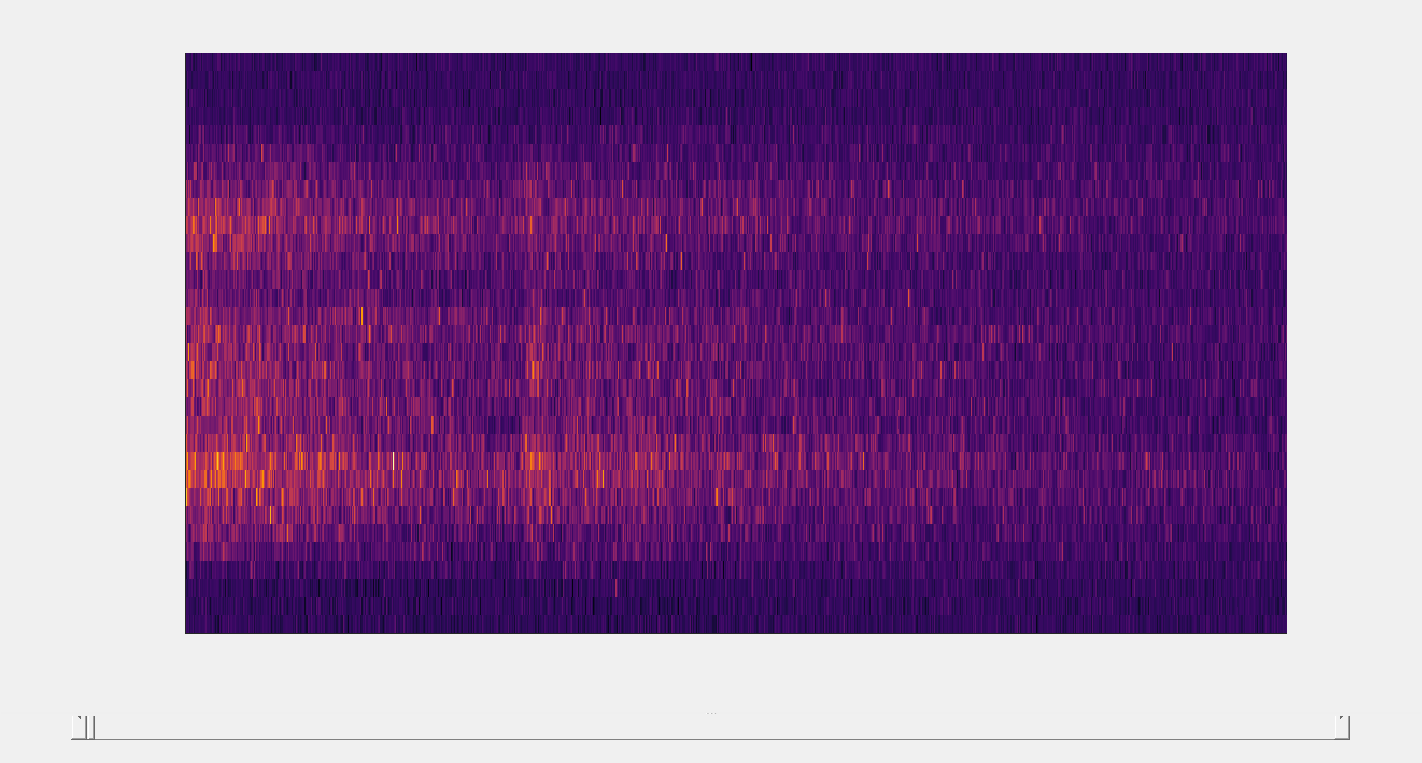

A2 = A(:, :, goodframes);
sliceViewer(permute(A2, [3 2 1]));
colormap inferno(1024);
axis normal;

## Import STEM-DP datacube

Unlike with the EELS data, we can directly interpolate the CBED patterns into the 4D STEM-DP datacube, as there is no pre-treatment necessary.

Found and removed 0 bad pixel timestamp(s)
ESI was paused 0 time(s).  Expecting 1 DP stack(s)


% When prompted, choose the file "DP_Movie.dm4"
[STEMDP, tsDP] = getDiffImage('STEMDP_TimeStamps.gtg');

% Due to the way that the data are recorded, a permutation is necessary in
% Matlab
STEMDP = permute(STEMDP, [2 1 4 3]);

Here, we check the map histogram, which tells us how many CBED patterns were assigned to each pixel

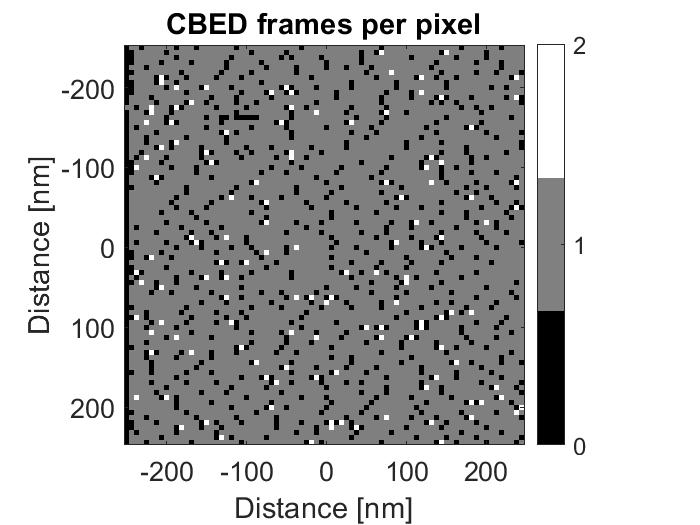

tsDP.maphistogram = tsDP.maphistogram'; % Permutation is required, as discussed above
figure('Color','w');
imagesc(x, x, tsDP.maphistogram);
axis image;
set(gca, 'colormap', gray(max(tsDP.maphistogram(:))+1));
colorbar;
title('CBED frames per pixel')
set(gca, 'FontSize', 16);
% plotImage(tsDP.maphistogram, 'Colormap', gray(max(tsDP.maphistogram(:))+1), 'Colorbar', true, ...
%     'Title', 'CBED frames per pixel');
set(findobj(gcf, 'Type', 'colorbar'), 'Ticks', [0:max(tsDP.maphistogram(:))]);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

### Explore the STEM-DP datacube

At the time of summarizing these data, I do not have a Matlab function to explore 4D Datasets effectively.  I recommend that one exports the datacube to [Hyperspy](https://hyperspy.org/) and uses the [PyXem](https://github.com/pyxem/pyxem) package.  For now, we will simply look at the virtual HAADF image, to ensure that the patterns were properly imported.  We will then generate to orientation masks using virtual dark field samples, which were determined by exploring the data in PyXem.  Finally, we will produce a "grain" mask that represents the entire iron grain under investigation.

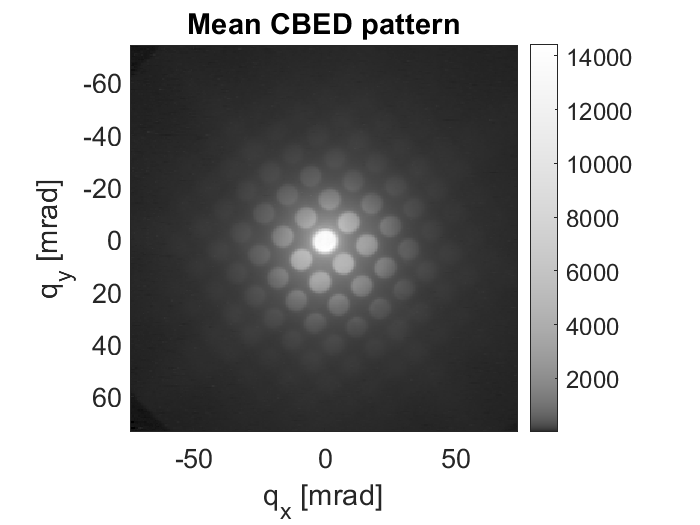

[rx, ry] = meshgrid(qx, qx);
Rc = sqrt((rx.^2 + ry.^2)) > 40 & sqrt((rx.^2 + ry.^2)) < qx(end); % HAADF range > 40 mrad
% Plot mean CBED pattern
figure('Color','w');
imagesc(qx, qx, mean(mean(STEMDP, 4), 3));
axis image;
colorbar;
title('Mean CBED pattern')
set(gca, 'FontSize', 16);
xlabel('q_x [mrad]');
ylabel('q_y [mrad]');
set(gca, 'colormap', imGamma(gray(10000), 0.3)); % Put a gamma curve on the grayscale colomap

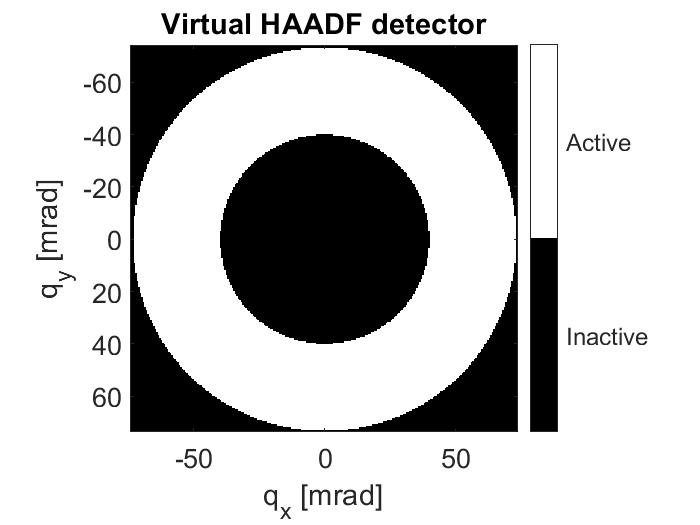

% Plot virtual HAADF detector
figure('Color','w');
imagesc(qx, qx, Rc);
set(gca, 'colormap', gray(2));
axis image;
colorbar;
title('Virtual HAADF detector')
set(gca, 'FontSize', 16);
set(findobj(gcf, 'Type', 'colorbar'), ...
    'Ticks', [0.25 0.75], 'TickLabels', {'Inactive', 'Active'}, ...
    'TickLength', 0);
xlabel('q_x [mrad]');
ylabel('q_y [mrad]');

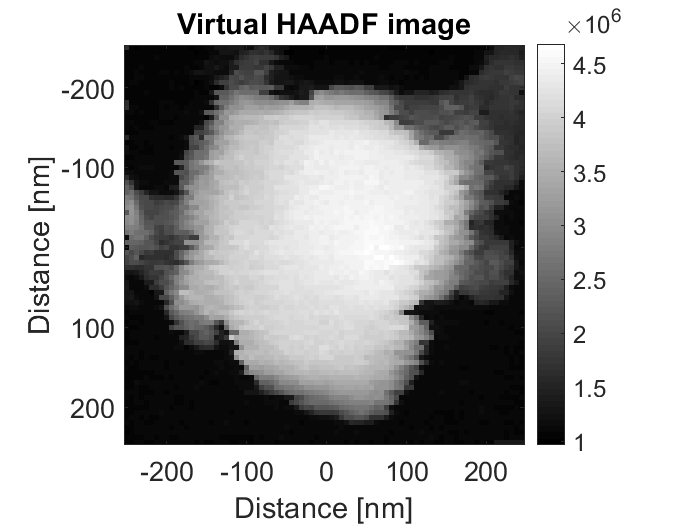

% Plot the virtual HAADF image
haadf = squeeze(sum(sum(STEMDP .* Rc, 2), 1));
figure('Color','w');
imagesc(x, x, haadf);
colormap gray;
axis image;
colorbar;
title('Virtual HAADF image')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

### Generate orientation masks

In this section, we use the STEM-DP data to generate orientation masks.  If one browses the data (for example using PyXem), one sees that some regions of the iron grain are closer to the [1 0 0] zone axis orientation than others.  To estimate this, we look at a Kikuchi line that varies quite a bit as the orientation changes.  This will give us an estimate of a zone-axis orientation vs. an orientation that is tilted further away.

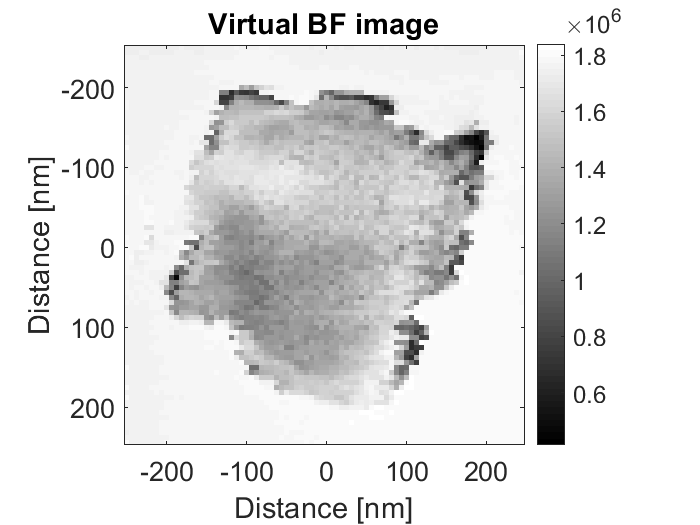

% Virtual Bright Field
vbf = squeeze(sum(sum(STEMDP(125:135, 125:135, :, :), 1), 2));
% plotImage(vbf, 'colorbar', true);
figure('Color','w');
imagesc(x, x, vbf);
colormap gray;
axis image;
colorbar;
title('Virtual BF image')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

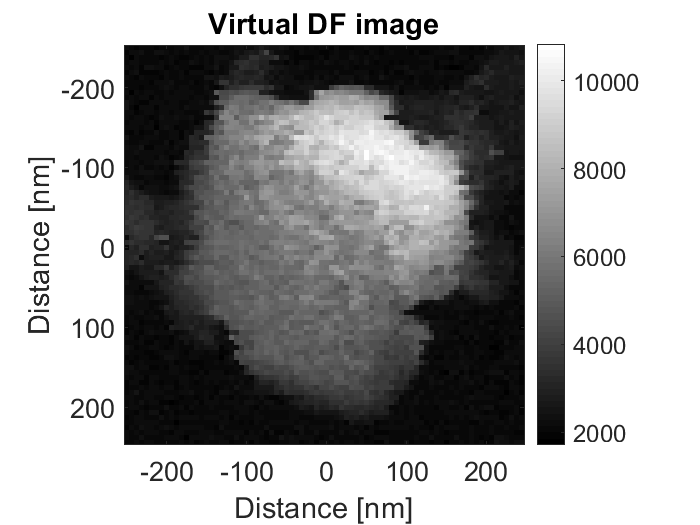


% Virtual Dark Field
vdf = squeeze(sum(sum(STEMDP(205:216, 18:26, :, :), 1), 2));
% plotImage(vdf);
figure('Color','w');
imagesc(x, x, vdf);
colormap gray;
axis image;
colorbar;
title('Virtual DF image')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

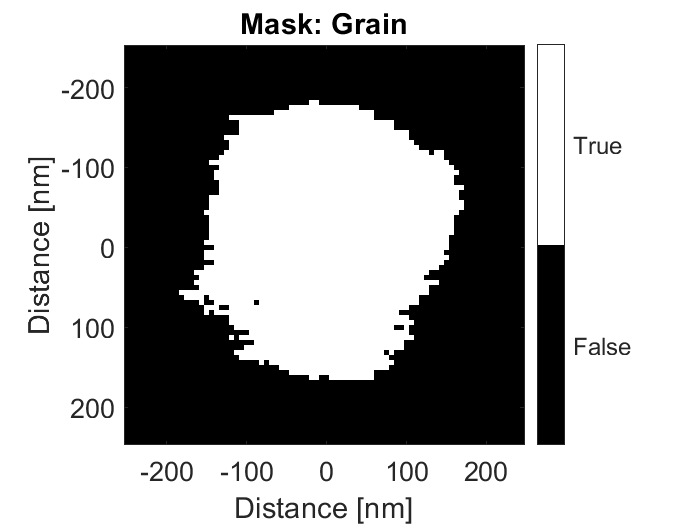

% Mask: Full grain
mask.grain = (vbf < 1.8e6 & vbf > 1e6) & haadf > 3.5e6;
% plotImage(mask.grain);
figure('Color','w');
imagesc(x, x, mask.grain);
set(gca, 'Colormap', gray(2));
colorbar;
set(findobj(gcf, 'Type', 'colorbar'), ...
    'Ticks', [0.25 0.75], 'TickLabels', {'False', 'True'}, ...
    'TickLength', 0);
axis image;
title('Mask: Grain')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

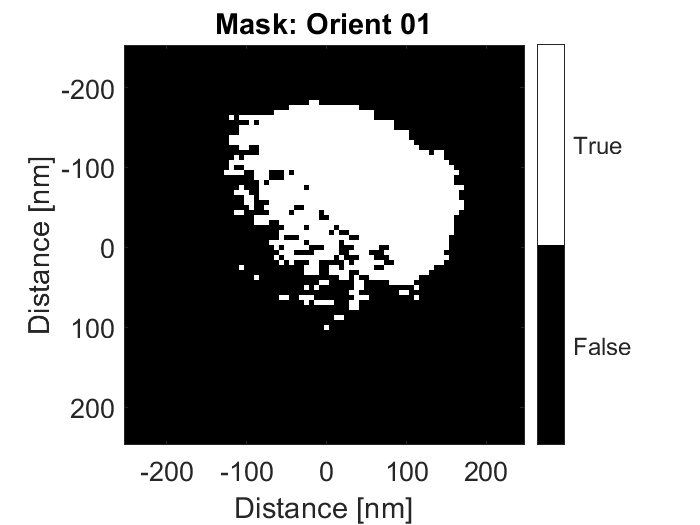


% Mask: Orient 01
mask.orient1 = vdf > 6000 & mask.grain;
% plotImage(mask.orient1);
figure('Color','w');
imagesc(x, x, mask.orient1);
set(gca, 'Colormap', gray(2));
colorbar;
set(findobj(gcf, 'Type', 'colorbar'), ...
    'Ticks', [0.25 0.75], 'TickLabels', {'False', 'True'}, ...
    'TickLength', 0);
axis image;
title('Mask: Orient 01')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

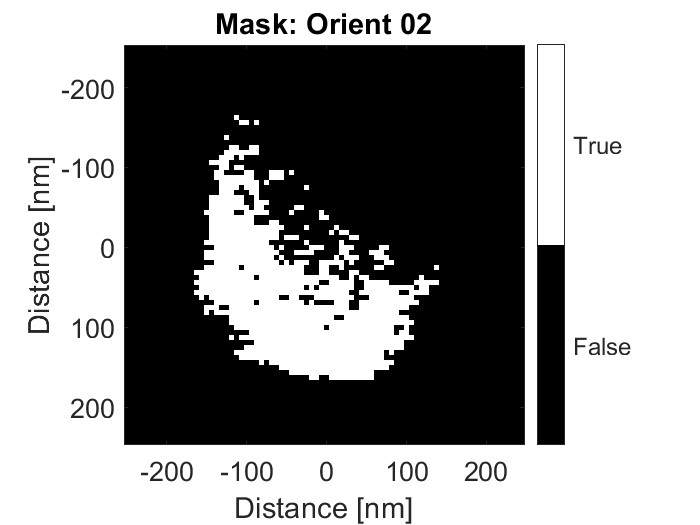


% Mask: Orient 02
mask.orient2 = (vdf < 6000 & vdf > 4000) & mask.grain;
% plotImage(mask.orient2);
figure('Color','w');
imagesc(x, x, mask.orient2);
set(gca, 'Colormap', gray(2));
colorbar;
set(findobj(gcf, 'Type', 'colorbar'), ...
    'Ticks', [0.25 0.75], 'TickLabels', {'False', 'True'}, ...
    'TickLength', 0);
axis image;
title('Mask: Orient 02')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

### CBED patterns for different orientations

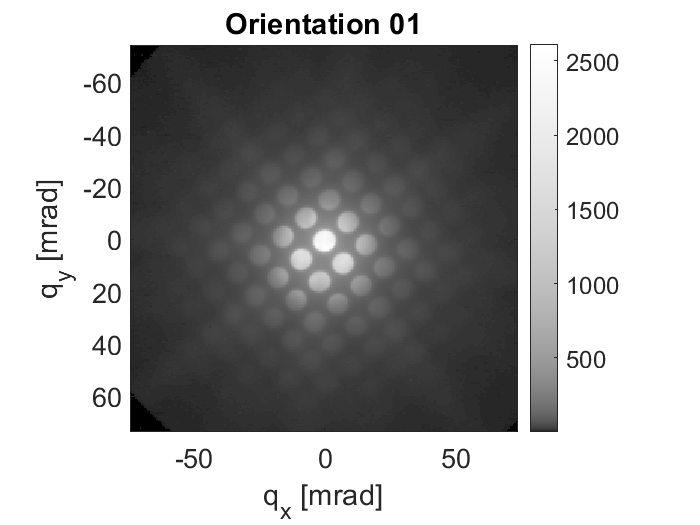

CBED.orient1 = squeeze(mean(mean(permute(STEMDP, [3 4 1 2]) .* mask.orient1)));
% plotImage(CBED.orient1, 'colormap', imGamma(gray(100000), 0.3), 'title', 'Orientation 01');
figure('Color','w');
imagesc(qx, qx, CBED.orient1);
axis image;
colorbar;
title('Orientation 01')
set(gca, 'FontSize', 16);
xlabel('q_x [mrad]');
ylabel('q_y [mrad]');
set(gca, 'colormap', imGamma(gray(1000), 0.3)); % Put a gamma curve on the grayscale colomap

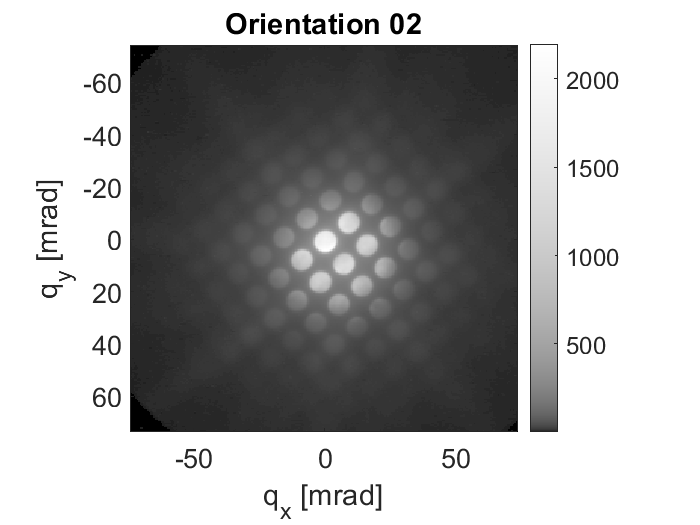

CBED.orient2 = squeeze(mean(mean(permute(STEMDP, [3 4 1 2]) .* mask.orient2)));
% plotImage(CBED.orient2, 'colormap', imGamma(gray(100000), 0.3), 'title', 'Orientation 02');
figure('Color','w');
imagesc(qx, qx, CBED.orient2);
axis image;
colorbar;
title('Orientation 02')
set(gca, 'FontSize', 16);
xlabel('q_x [mrad]');
ylabel('q_y [mrad]');
set(gca, 'colormap', imGamma(gray(1000), 0.3)); % Put a gamma curve on the grayscale colomap

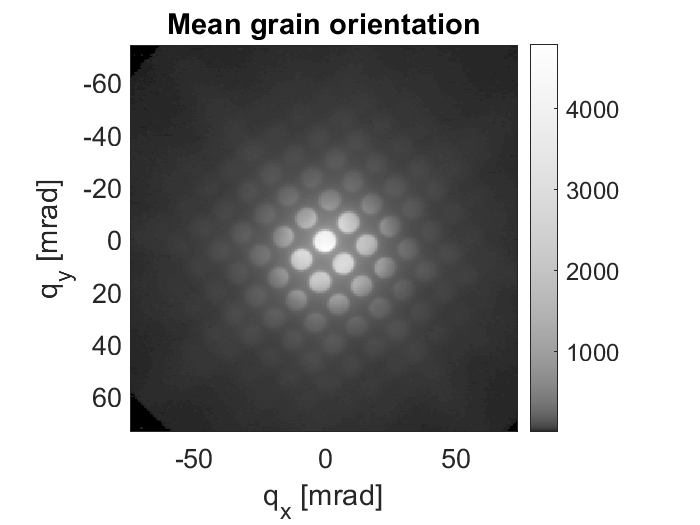

CBED.grain = squeeze(mean(mean(permute(STEMDP, [3 4 1 2]) .* mask.grain)));
% plotImage(CBED.grain, 'colormap', imGamma(gray(100000), 0.3), 'title', 'Mean Orientation');
figure('Color','w');
imagesc(qx, qx, CBED.grain);
axis image;
colorbar;
title('Mean grain orientation')
set(gca, 'FontSize', 16);
xlabel('q_x [mrad]');
ylabel('q_y [mrad]');
set(gca, 'colormap', imGamma(gray(1000), 0.3)); % Put a gamma curve on the grayscale colomap

## 4D EELS pretreatment

### X-Ray spike identification and removal

In this section, we identify x-ray spikes and remove them.  The x-ray spikes are uncovered by looking for datapoints that deviate from a moving average by more than 5 sigma.  The area surrounding these datapoints is then dialated and they are replaced by a linear interpolation from the nearest datapoints.

spikes = getXRaySpikeModel(A2, 'medWin', 17, ...
    'sigma', 5, 'plot', false, 'method', 'replace', 'dilate', 5);
A3 = applyXRaySpikeModel(A2, spikes);

### Rough energy alignment (correcting for the drift-tube shift)

This first step corrects for the sawtooth drift tube offset that was applied during the data acquisition.  Since the offset was acquired in a separate thread, the exact values are unknown.  We thus need to perform cross-correlation to retrieve them.

In this first step, we first vertically sum the dataset (integrate along $q_y$).  The assumption here is that this is what happens under standard EELS acquisition.  Also, each 2D EELS frame was acquired with the same drift tube offset, and this integration helps with the signal to noise ratio.  Once this is done, we find a good looking spectrum that we can use as a reference.

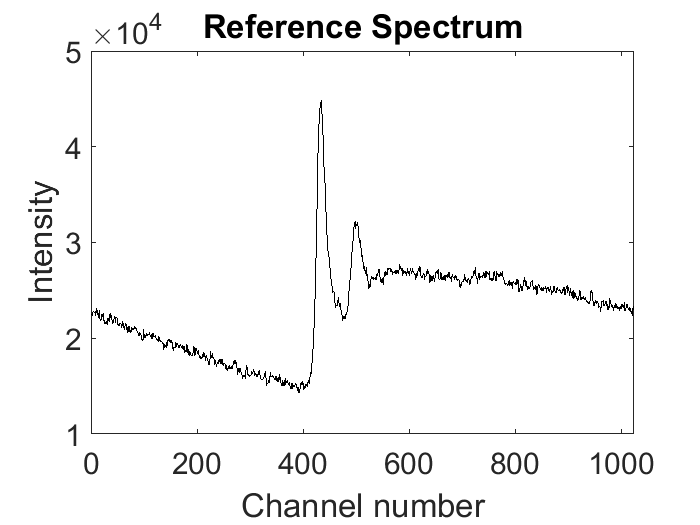

L = squeeze(sum(A3(1025:end, :, :), 2));
xL = 1:length(L);
ref = sum(L(:, 2960:2970), 2);
figure('color', 'w');
plot(ref, 'k');
xlabel('Channel number');
ylabel('Intensity');
set(gca, 'FontSize', 18);
title('Reference Spectrum');

Now we perform the cross-correlation using the function `getISOmap`.

isomap = getISOmap(L, 'ref', ref, ...
    'diffOrder', 0, 'smooth', true, 'progressbar', false, 'interp', 10);


Getting isomap without parallel computing toolbox...Elapsed time is 4.051086 seconds.


We can check how close were were to retrieving the sawtooth function by plotting all of the shift values.

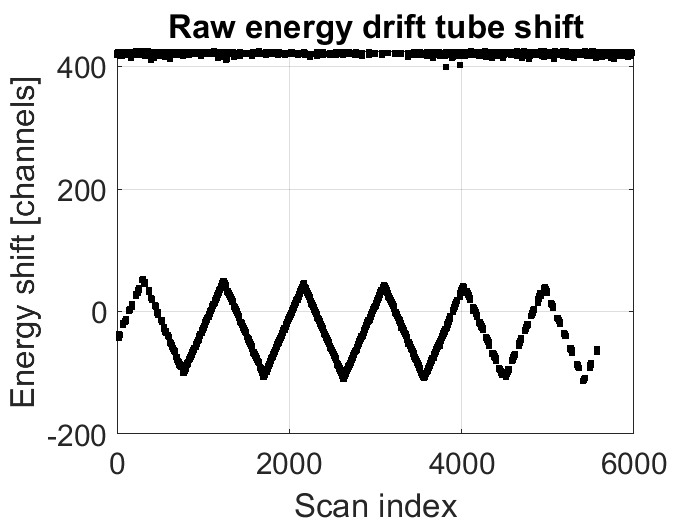

fig(1) = figure('color', 'w');
plot(xL, isomap.shift, 'k.', 'MarkerSize', 10);
xlabel('Scan index');
ylabel('Energy shift [channels]');
set(gca, 'fontsize', 18);
grid on;
title('Raw energy drift tube shift');

The sawtooth function is clearly visible.  In regions where the Fe $L_{2,3}$ edges were too weak (such as over the background), the cross-correlation failed, giving a very large erroneous value.

### Correct for outliers

We can easily correct for the erroneous drift tube offset datapoints by selecting extreme values.  We also estimate the drift tube towards the end of the ESI acquisition by modelling the sawtooth function (although this is admittedly not necessary, as these datapoints don't contain iron and, thus, will not be used in the EMCD analysis).

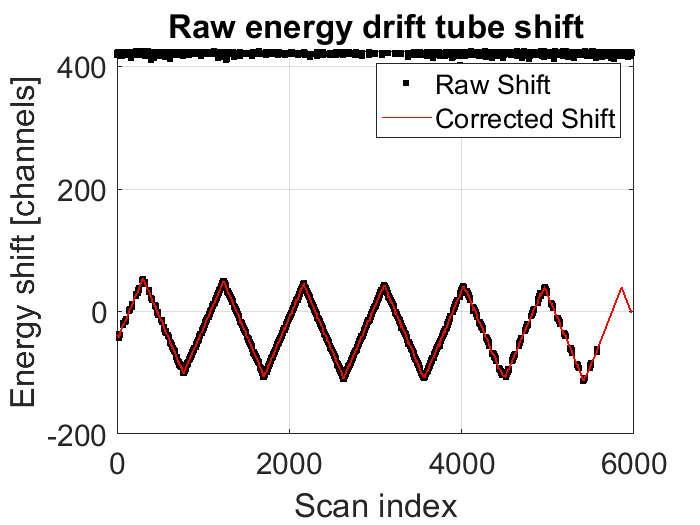

badpx = isomap.shiftRaw > 80;
isomap.shift = filloutliers(isomap.shiftRaw, 'linear', 'OutlierLocations', badpx);
lastGoodPx = find(~badpx, 1, 'last');
% Manual estimation for pixels after the iron edge ends
isomap.shift(lastGoodPx + 1 : end) = 0.36.*xL(1 : length(L) - lastGoodPx) + isomap.shift(lastGoodPx);
isomap.shift(isomap.shift > max(isomap.shift(4300:lastGoodPx)) & xL > lastGoodPx) = ...
    max(isomap.shift(4300:lastGoodPx)) - (isomap.shift(isomap.shift > max(isomap.shift(4300:lastGoodPx)) & xL > lastGoodPx) ...
    - max(isomap.shift(4300:lastGoodPx)));

figure('color', 'w');
plot(xL, isomap.shiftRaw, 'k.', 'MarkerSize', 10, 'DisplayName', 'Raw Shift');
hold on;
plot(xL, isomap.shift, 'r', 'LineWidth', 1, 'DisplayName', 'Corrected Shift');
legend;
xlabel('Scan index');
ylabel('Energy shift [channels]');
set(gca, 'fontsize', 18);
grid on;
title('Raw energy drift tube shift');

### Apply the rough ISOmap and visualize it

The offset correction is now applied to the full 4D EELS datacube by iterating through each $q_y$ vector.

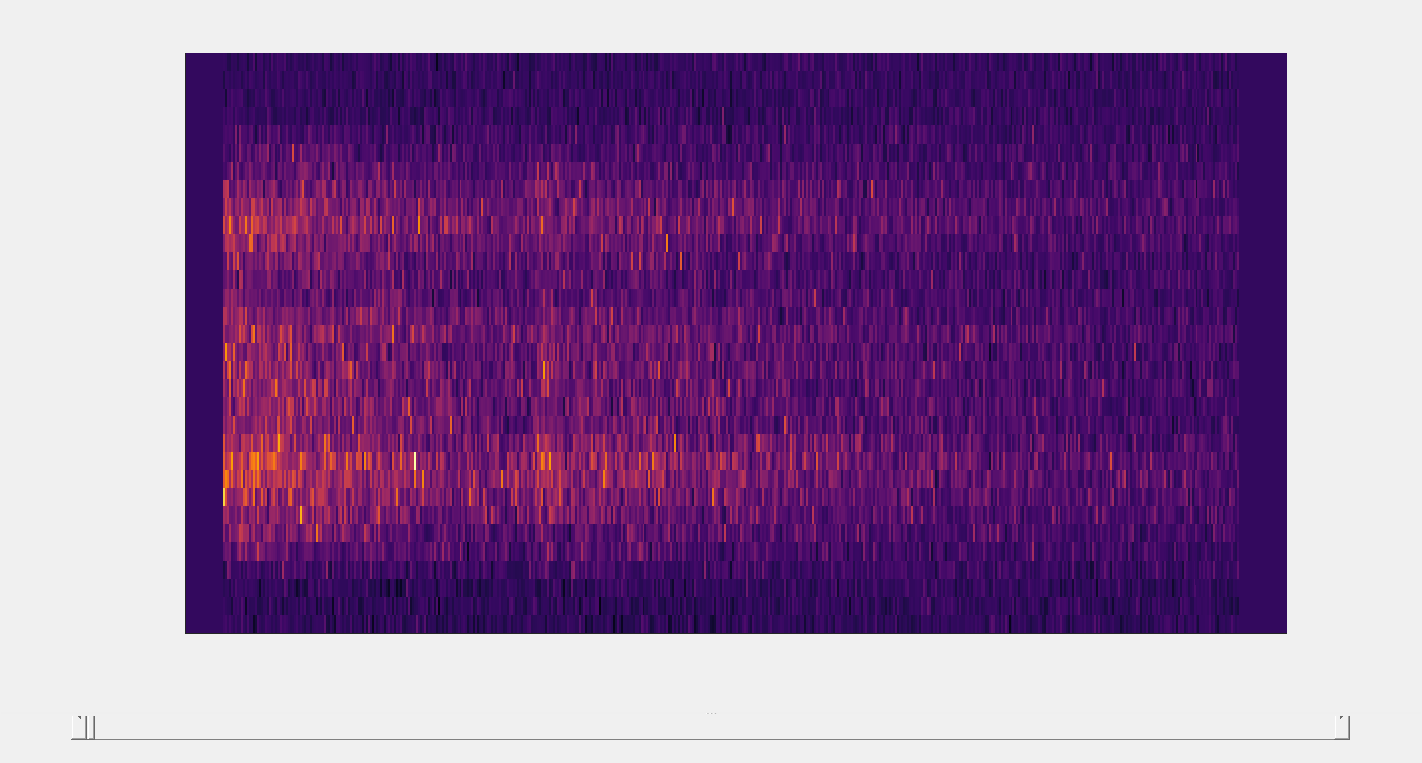

for idx = 1:32
    [B(:, idx, :), cropMask, scanMask] = applyISOmap(A3(:, idx, :), isomap, 'crop', false);
end

sliceViewer(permute(B, [3 2 1]));
colormap inferno(1024);
axis normal

### Fine energy drift correction

As discussed in the manuscript, the above energy drift correction only corrects (approximately) for the drift tube offset, providing some gain averaging.  However, close inspection of the EELS data reveals that there is some energy drift dependence on $q_y$ as well.  We will attempt to remove this by using a peak shifting methodology based on regressing the spectral mean and its first derivation against the raw data.  We begin with the shifted dataset.

mask.Ref = 1500:1615; %channels.  Only select the Fe L3
mask.meanEELSSpectra = mean(B, 1); % Only perform this correction on ironk
mask.meanEELSSpectra = squeeze(mask.meanEELSSpectra);
mask.BG = mask.meanEELSSpectra < 28; %Based on 4D summation

% testShift is designed for typical 3D hyperspectral EELS datacubes, which
% we currently have, since we have not interpolated to an (x, y) datacube.
[~, shifts] = taylorShift(make2D(B(mask.Ref, :, :)), 'nIter', 5, 'mask', ~mask.BG(:));


Iteration number 01
Iteration number 02
Iteration number 03
Iteration number 04
Iteration number 05

We now display the shift as a function of both scan index (pixel position) and $q_y$.  We notices that there is a noticable energy shift between the middle region (low values of $q_y$) and the outer regions.  This 

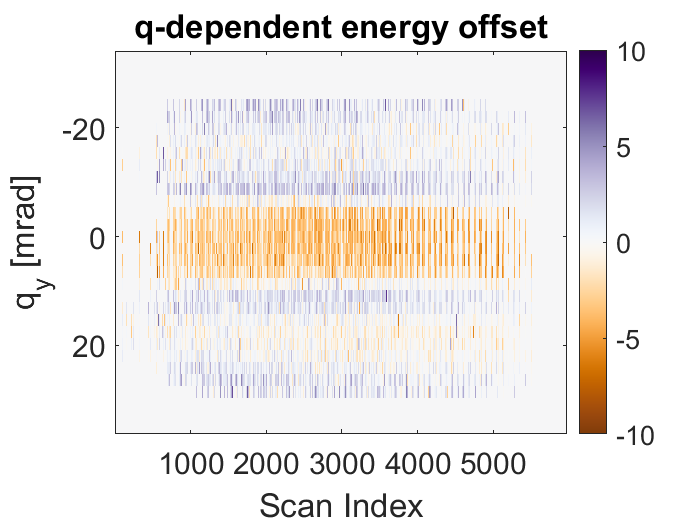

figure('color', 'w');
imagesc(1:length(L), qy, reshape(sum(shifts, 2), 32, length(L)));
axis normal;
colorbar;
set(gca, 'Colormap', brewermap(1024, 'PuOr'));
% set(gca, 'CLim', max(abs(get(gca, 'CLim'))) .* [-1 1]); % Center around zero
set(gca, 'CLim', 10 .* [-1 1]); % Center around zero
set(gca, 'FontSize', 18);
xlabel('Scan Index');
ylabel('q_y [mrad]');
title('q-dependent energy offset');

Now, we take the energy offset map above and add it to the drift tube offset from the previous section.  This is then our final energy offset map, which we will apply to the raw data.

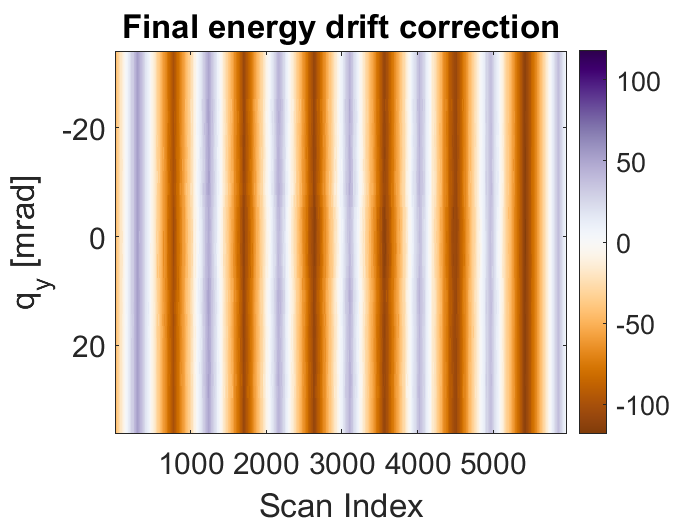

% Drift tube offset
isomapFinal = isomap;

% Expand to qy x L dimensions
isomapFinal.shift = repmat(isomap.shift, [32 1]);

% Add the q-dependence to the drift tube offset
isomapFinal.shift = isomapFinal.shift + reshape(sum(shifts, 2), 32, length(L));

% Plot the result for inspection
% plotImage(isomapFinal.shift, 'colormap', inferno(1024), 'colorbar', true, 'centerzero', true, 'Title', 'Total Energy Adjust');
figure('Color','w');
imagesc(1:length(L), qy, isomapFinal.shift);
axis normal;
colorbar;
set(gca, 'Colormap', brewermap(1024, 'PuOr'));
set(gca, 'CLim', max(abs(get(gca, 'CLim'))) .* [-1 1]); % Center around zero
set(gca, 'FontSize', 18);
xlabel('Scan Index');
ylabel('q_y [mrad]');
title('Final energy drift correction');

### Apply the complete energy drift offset

We now return to the original (raw) dataset and apply the full energy drift correction.  This includes both the drift tube offset as well as the $q_y$-dependent correction.  The result is saved in variable `C`, which is ready for interpolation into a 4D datacube (allowing it to be correlated to the STEM-DP datacube through the x and y spatial dimensions).

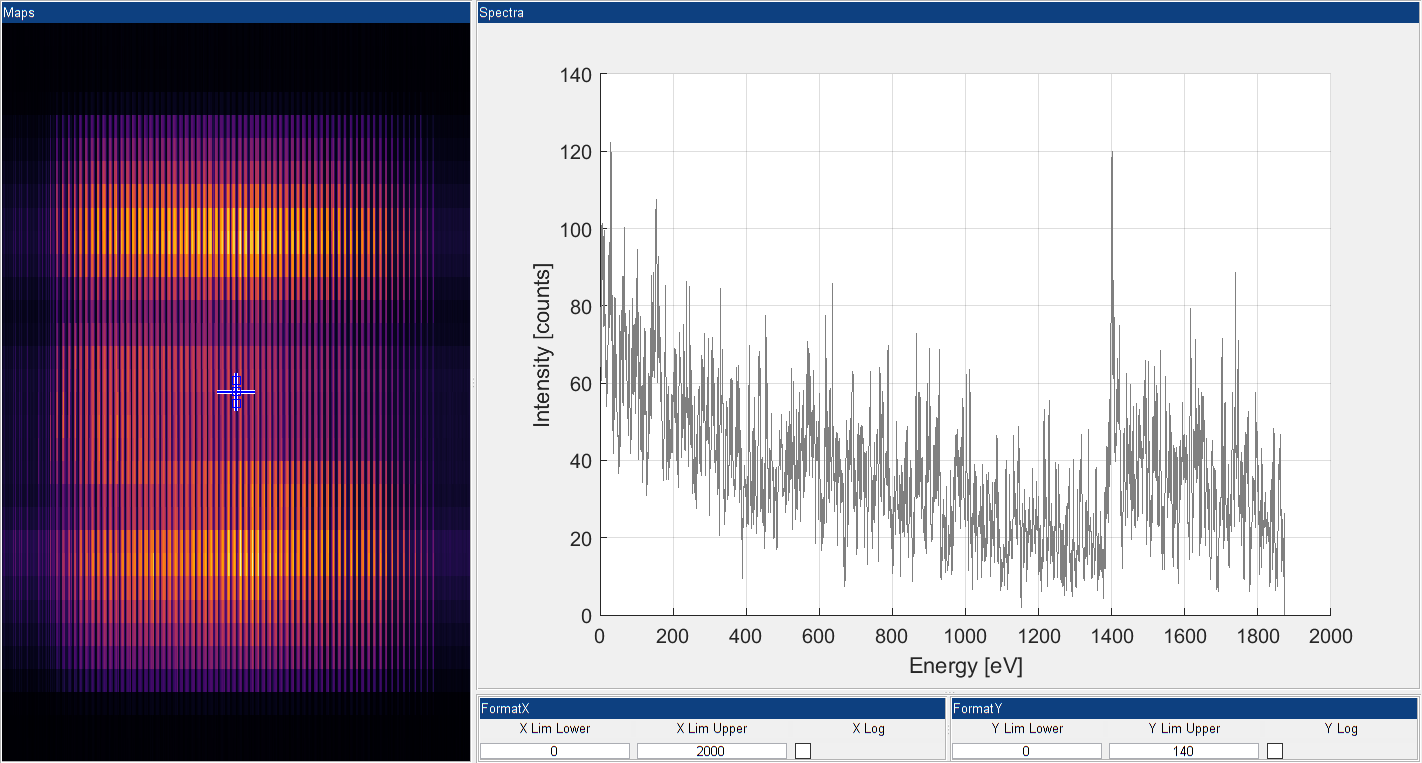

C = applyISOmap(A3, isomapFinal, 'crop', true); % A4 uses IGA, A3 does not
viewESI(1:size(C, 1), 1, C); axis normal; colormap inferno(1024);

We also generate a new energy vector at this stage.  Channel 1401, which is the maximum of the Fe $L_3$ edge, is defined to be 709 eV.  The new energy vector is saved as variable `e`.

e = (((0:size(C, 1)-1) - 1401).*0.2 + 709)';

### Interpolation to 4D datacube

For the final preprocessing stage, we need to reorganize the stack of 2D EELS frames (dimensions $\Delta E \times q_y \times N$) into a 4D datacube (dimensions $\Delta E \times q_y \times x \times y$).  We also take this opportunity to focus only on the Fe $L_{2,3}$ edges as well as remove the values of $q_y$ that fall outside of the passthrough region of the aperture.

goodQ = 5:28; % Select qy values that reside within the aperture holes
mskE = 1000:1800; % Select the higher energy loss
nRows = 80; % Number of rows (same as STEM-DP)
nCols = 80; % Number of columns (same as STEM-DP)
qy2 = qy(goodQ); % Crop the qy vector
clear temp temp2 maphistogram

% Preallocate the final 4D EELS variable
DPEELS = zeros(length(mskE), length(goodQ), nCols, nRows);

To write the 2D EELS frames into a 4D datacube, we will iterate through each row.  The timestamps (in variable `ts`) tell us which frame index corresponds to the beginning and end of each row.  As we will see, while most probe positions can be assigned a single 2D EELS frame, some will be missing and some will have excess frames.  To get around this, we can use a nearest neighbor interpolation for each row, which is what the code below achieves.

for idx = 1:(nRows-1)
    temp = C(mskE, goodQ, ts.idxNewRow(idx):(ts.idxNewRow(idx+1)-1));
    temp2 = resampleESI(temp, [length(mskE) length(goodQ) nCols], 'nearest');
    DPEELS(:, :, ts.finalrowindex(idx):ts.finalrowindex(idx+1)-1) = temp2;
    maphistogram(:, idx) = ...
        histcounts(ts.activeframes(ts.idxNewRow(idx) : (ts.idxNewRow(idx+1)-1)), ...
        [ts.pxbegin(ts.finalrowindex(idx) : ts.finalrowindex(idx+1)-1); ts.pxend(ts.finalrowindex(idx+1)-1)]);
end

We now nearly need to reshape the 4D EELS datacube into the four dimensions and permute it for convenience.

DPEELS = reshape(DPEELS, length(mskE), length(goodQ), nCols, nRows);
DPEELS = permute(DPEELS, [2 1 4 3]);

We can confirm that the result is reasonable by integrating along both the $\Delta E$ and $q_y$ dimensions, yielding an $x, y$ map that represents the total inelastic scattering cross sections.

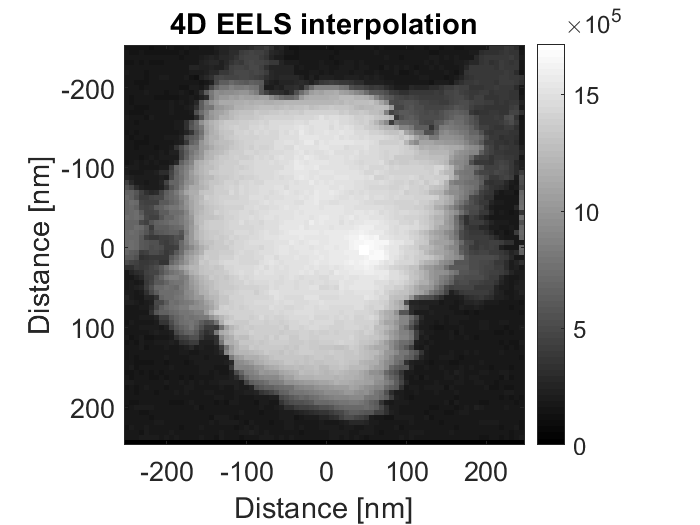

figure('Color','w');
imagesc(x, x, squeeze(sum(sum(DPEELS, 2), 1)));
colormap gray;
axis image;
colorbar;
title('4D EELS interpolation')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');

Finally, we can check how many 2D EELS frames were acquired at each $x, y$ position by inspecting the map histogram, as previously done for the STEM-DP datacube.

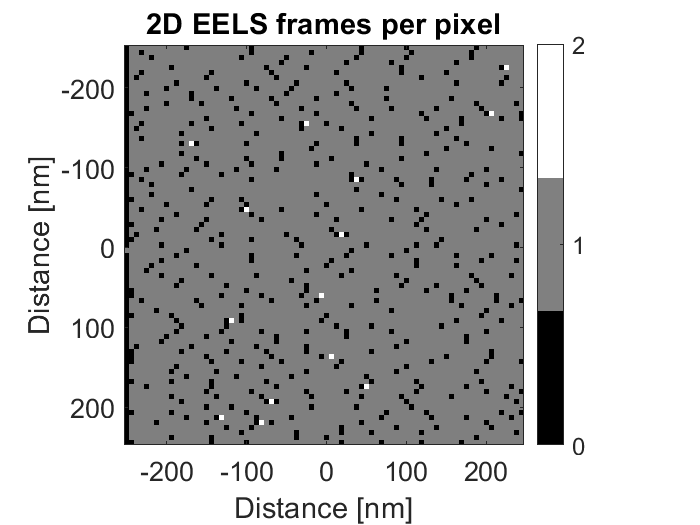

maphistogram = maphistogram'; % Transpose x, y
figure('Color','w');
imagesc(x, x, maphistogram);
set(gca, 'colormap', gray(max(maphistogram(:))+1));
axis image;
colorbar;
title('2D EELS frames per pixel')
set(gca, 'FontSize', 16);
xlabel('Distance [nm]');
ylabel('Distance [nm]');
set(findobj(gcf, 'Type', 'colorbar'), 'Ticks', [0:max(maphistogram(:))]);

This marks the end of the pretreatment stage for the 4D EELS dataset.  We now proceed to the extraction of candidate EMCD signals.

## Candidate EMCD signal extraction:

### Necessary function handles

q is a simple function handle that selects the opposing q-values for the summed 2D EELS spectra.  This assumes that the center of the summation lies at `q = 0`.  This was determined by careful placement of the patterned aperture during experimental acquisition, and the centering we belive to be most accurate is applied here.  If you want to see the effect of changing this center value, then re-run the section above with different values for `goodQ`.

q = @(S, ind) [sum(S(ind, :), 1); sum(S(end-ind+1, :), 1)]';

`sp` is a function handle that sharpens one of the spectra.  The approach is a standard removal of the second derivative.  Validation of this approach can be performed by integrating the second derivative.  If there is a zero-crossing between the L3 and L2 peaks, then the area under the peaks will not change and, hence, this will not directly bias the calculation of mL/mS.  This sharpening step is necessary since there is a very slight energy blur that arises from spectrometer errors.  The sharpening routine is parameterized by multiplying the second derivative by a scalar value (k) and this is what is allowed to vary in the optimization code for EMCD signal extraction.  This function handle serves to set an initial starting parameter, which is occasionally needed to avoid reaching a local minimum.  This is something that you can play around with to see the result to get a feel for what it does to the data.  The starting paremeter used below was empirically determined, but typically was in the range of -1 to -2.

sp = @(Sp, k) Sp - k.*gradient(gradient(smooth(Sp)));

To ensure that the sp does not change the area under the curve, we test it:

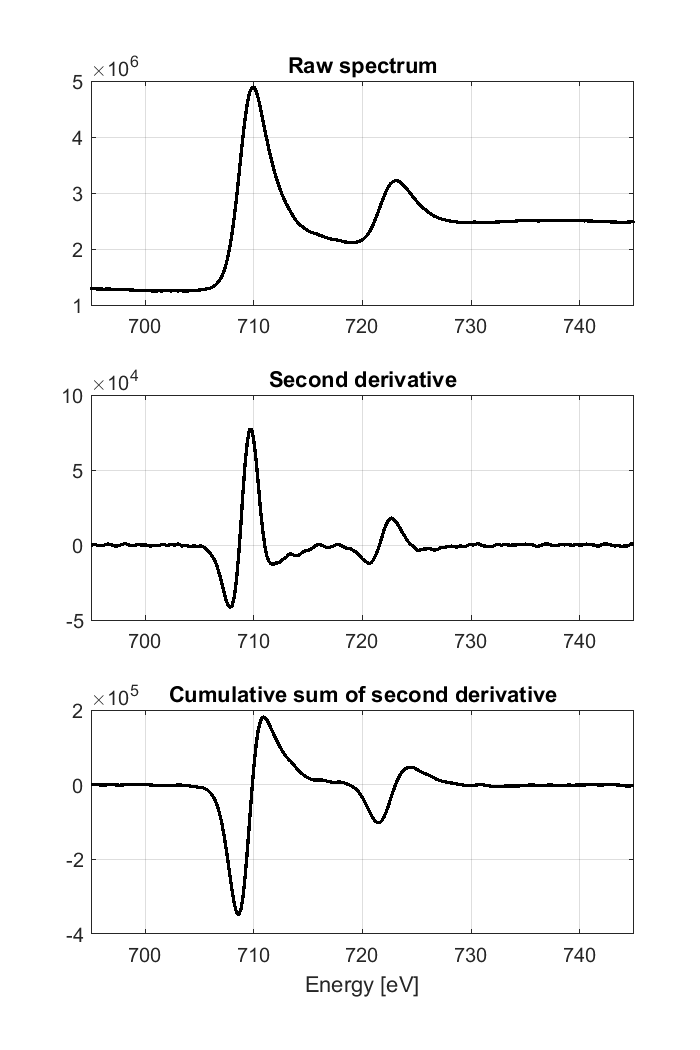

DPEELSsum.all = sum(sum(DPEELS.*permute(mask.grain, [4 3 1 2]), 4), 3);
testSharpening = q(DPEELSsum.all, 1:12);
testSharpening(:, 1) = []; % Remove chiral plus

e3 = ((1:size(testSharpening, 1))-find(testSharpening(:, 1) == max(testSharpening(:, 1)))).*0.2 + 710;
e3 = e3(:);

figure('color', 'w');
subplot(3, 1, 1);
% Plot the raw spectrum
plot(e3, testSharpening, 'k', 'LineWidth', 2);
title('Raw spectrum');
subplot(3, 1, 2);
% Plot the second derivative, scaled by -1 (causes broadening).  Smoothed
% first to reduce the noise contribution
plot(e3, -1*gradient(gradient(smooth(testSharpening))), 'k', ...
    'LineWidth', 2);
title('Second derivative');
subplot(3, 1, 3);
% Plot the cumulative sum of the second derivative (which is basically the
% first derivative).  The values between Fe L3 and L2 are close to 0;
% hence, the area under the curves does not change significantly.
plot(e3, cumsum(-1*gradient(gradient(smooth(testSharpening)))), 'k', ...
    'LineWidth', 2);
title('Cumulative sum of second derivative');
set(findall(gcf, 'type', 'axes'), 'xlim', [695 745], 'FontSize', 12, ...
    'XGrid', 'on', 'YGrid', 'on');
xlabel('Energy [eV]');
set(gcf, 'Position', [1 1 1 2] .* get(gcf, 'Position'));

### Using `mask.grain` and all $q_y$ values

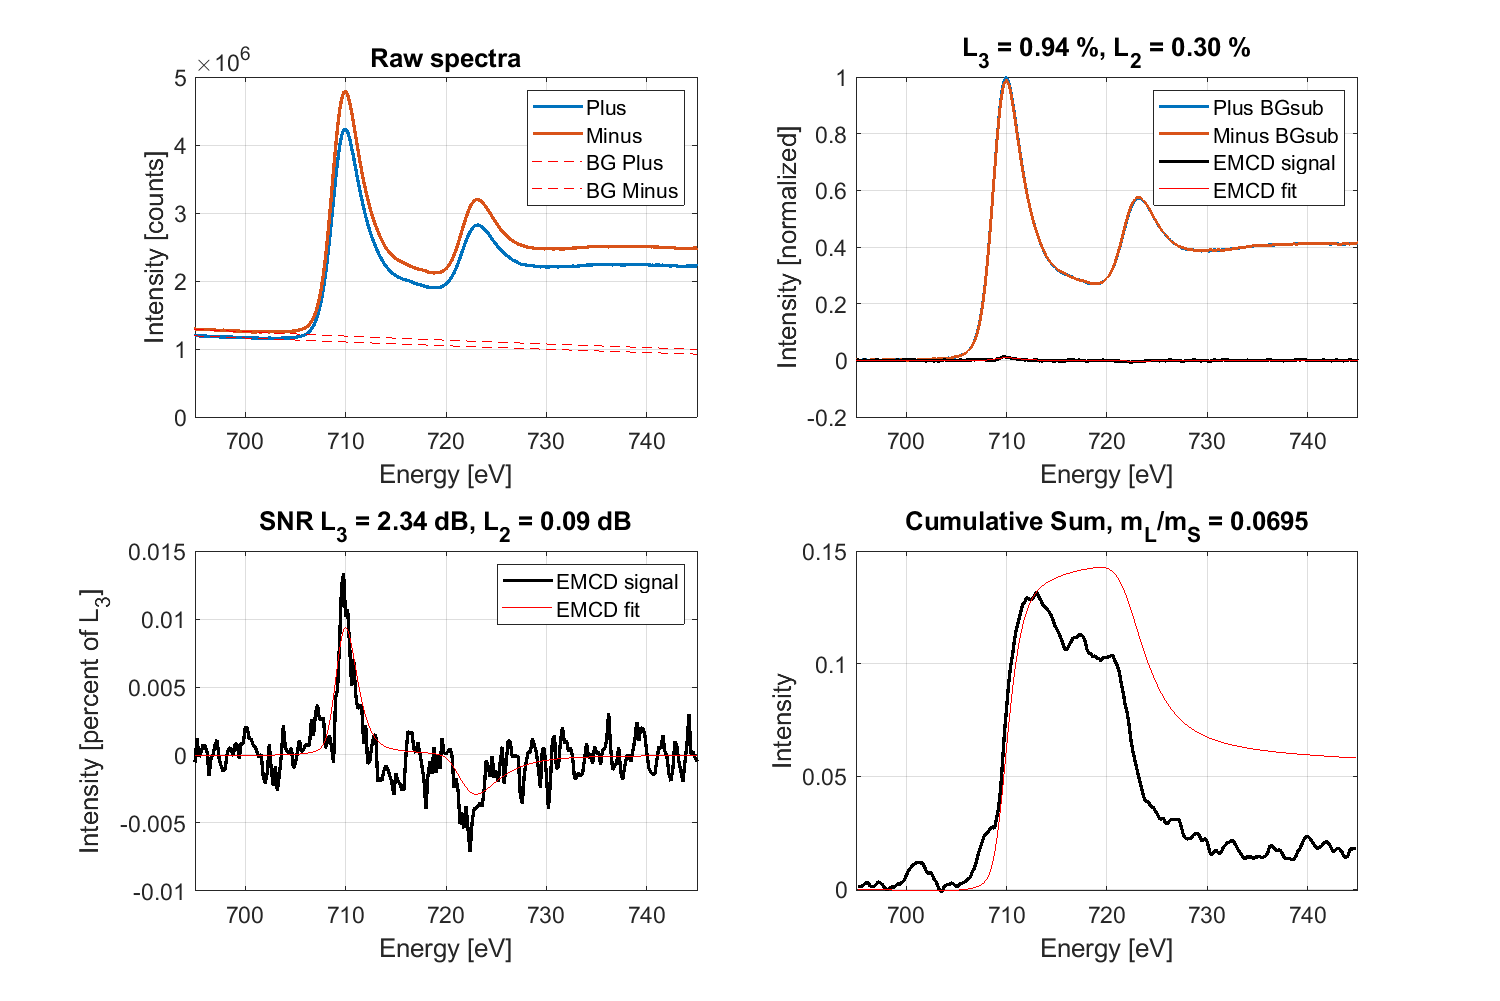

win.pre = [650 700];
win.post = [730 745];

DPEELSsum.all = sum(sum(DPEELS.*permute(mask.grain, [4 3 1 2]), 4), 3);

tmp = q(DPEELSsum.all, 1:12);

e3 = ((1:size(tmp, 1))-find(tmp(:, 1) == max(tmp(:, 1)))).*0.2 + 710;
e3 = e3(:);

[fo, mLmS, fStruct] = optimMLMS(e3, tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
    'preModel', 'Power Law', ...
    'postModel', 'Linear', ...
    'SScalculation', 'Decoupled', ...
    'sigModel', 'GLmix', ...
    'xlim', [695 745], ...
    'deblur', true, ...
    'shift', true, ...
    'algorithm', 'active-set');

plotEMCDfitCum(fStruct, 'xlim', [695 745]);

### Using` mask.grain` (integral over all orientations) and restricted $q_y$

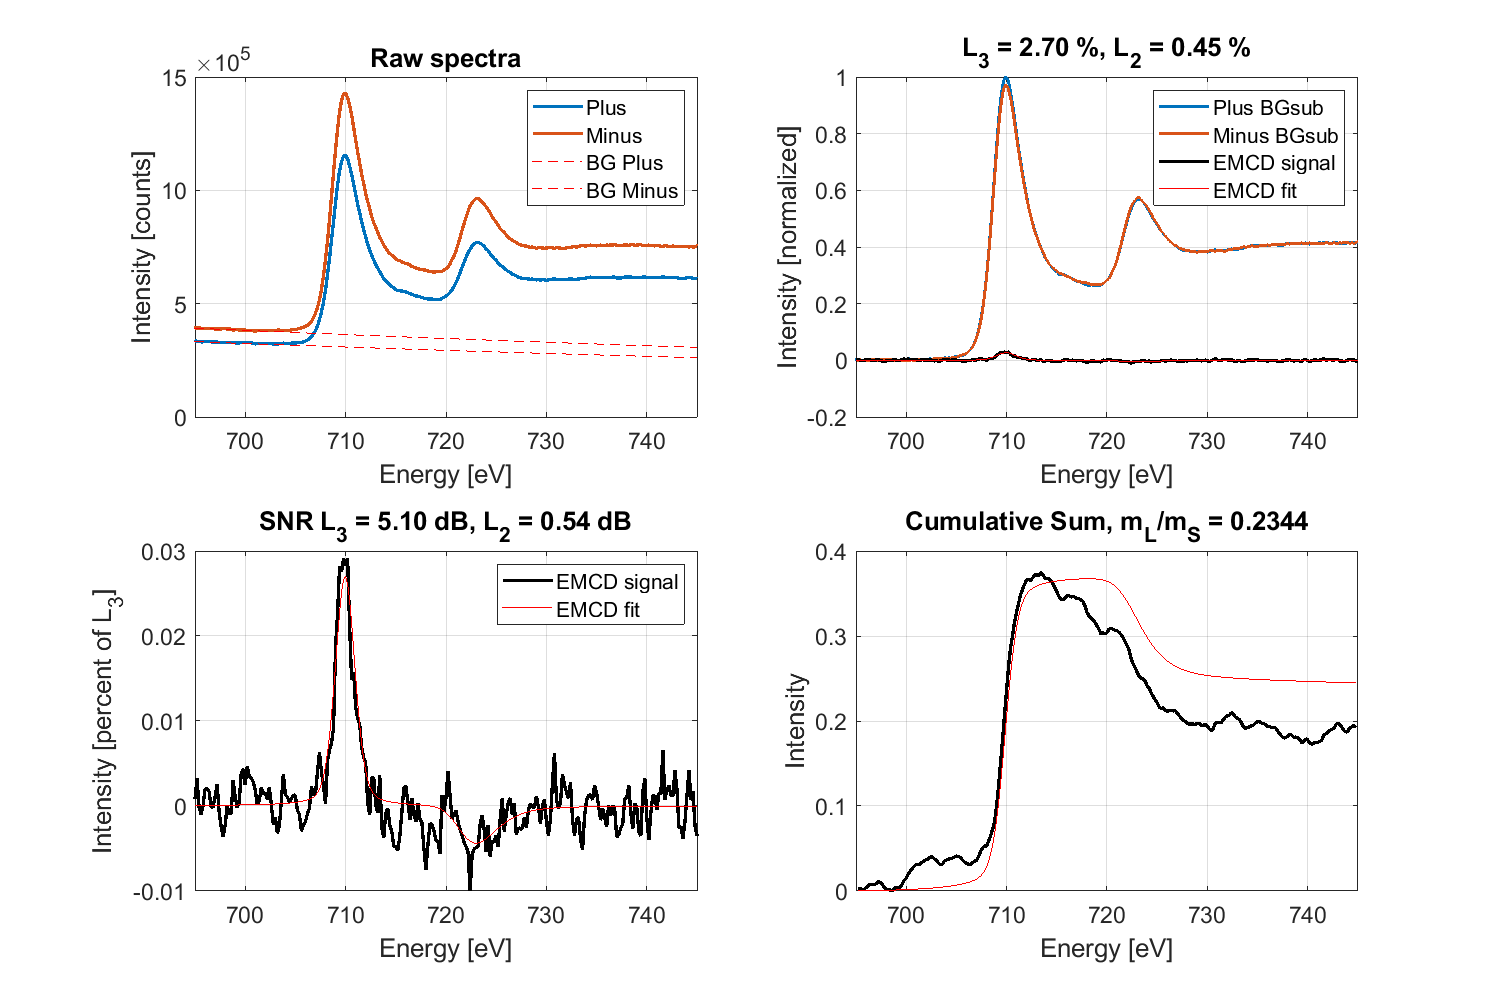

win.pre = [650 700];
win.post = [730 745];

DPEELSsum.grain = sum(sum(DPEELS.*permute(mask.grain, [4 3 1 2]), 4), 3);

tmp = q(DPEELSsum.grain, 1:4);

e3 = ((1:size(tmp, 1))-find(tmp(:, 1) == max(tmp(:, 1)))).*0.2 + 710;
e3 = e3(:);

[fo, mLmS, fStruct] = optimMLMS(e3, tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
    'preModel', 'Power Law', ...
    'postModel', 'Linear', ...
    'SScalculation', 'Decoupled', ...
    'sigModel', 'GLmix', ...
    'xlim', [695 745], ...
    'deblur', true, ...
    'shift', true, ...
    'algorithm', 'active-set');

plotEMCDfitCum(fStruct, 'xlim', [695 745]);

### Using `mask.orient01` `(`close to zone axis) and restricted $q_y$

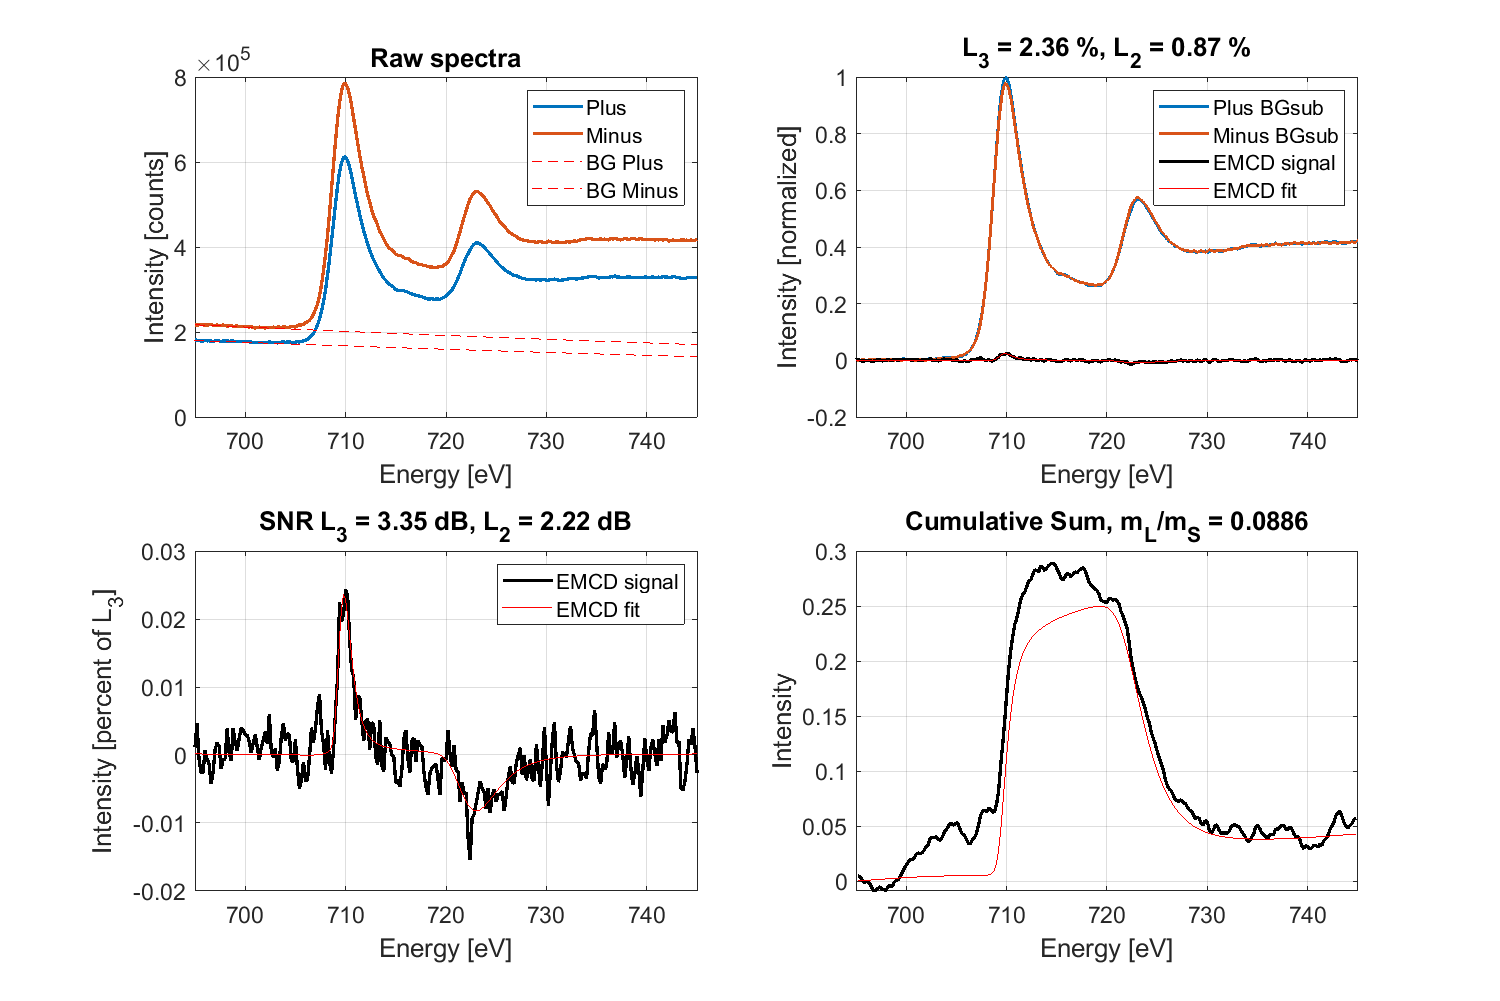

win.pre = [650 700];
win.post = [730 745];

DPEELSsum.orient1 = sum(sum(DPEELS.*permute(mask.orient1, [4 3 1 2]), 4), 3);

tmp = q(DPEELSsum.orient1, 1:4);

e3 = ((1:size(tmp, 1))-find(tmp(:, 1) == max(tmp(:, 1)))).*0.2 + 710;
e3 = e3(:);

[fo, mLmS, fStruct] = optimMLMS(e3, tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
    'preModel', 'Power Law', ...
    'postModel', 'Linear', ...
    'SScalculation', 'Decoupled', ...
    'sigModel', 'GLmix', ...
    'xlim', [695 745], ...
    'deblur', true, ...
    'shift', true, ...
    'algorithm', 'active-set');

plotEMCDfitCum(fStruct, 'xlim', [695 745]);

### Using` mask.orient02` (tilted away from zone axis) and restricted $q_y$

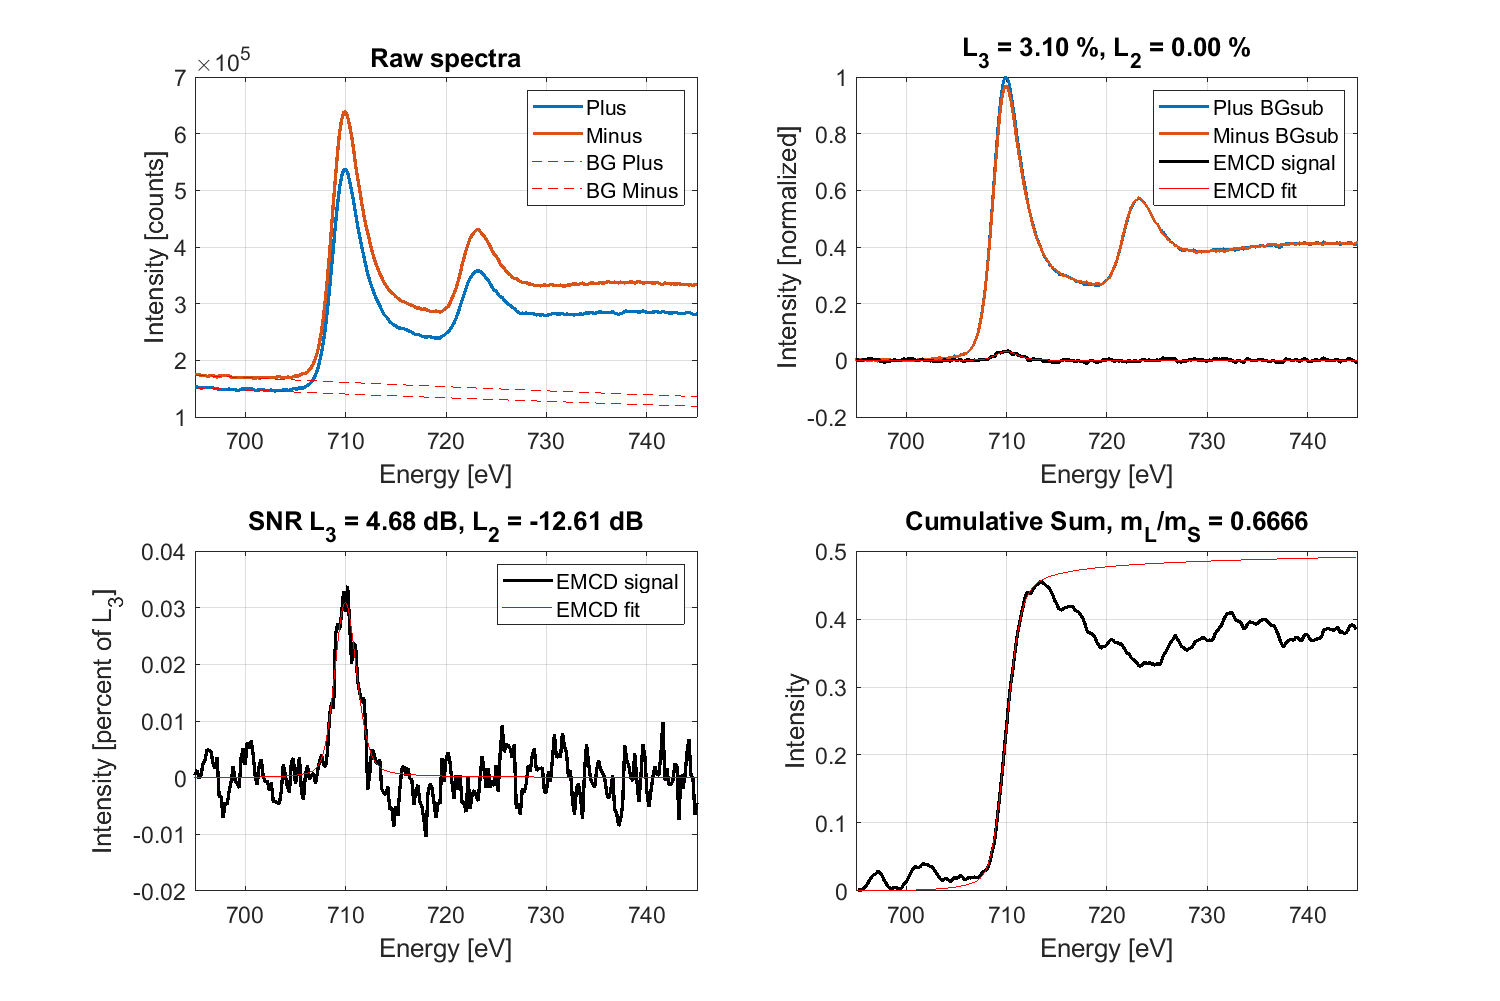

win.pre = [650 700];
win.post = [730 745];

DPEELSsum.orient2 = sum(sum(DPEELS.*permute(mask.orient2, [4 3 1 2]), 4), 3);

tmp = q(DPEELSsum.orient2, 1:4);

e3 = ((1:size(tmp, 1))-find(tmp(:, 1) == max(tmp(:, 1)))).*0.2 + 710;
e3 = e3(:);

[fo, mLmS, fStruct] = optimMLMS(e3, tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
    'preModel', 'Power Law', ...
    'postModel', 'Linear', ...
    'SScalculation', 'Decoupled', ...
    'sigModel', 'GLmix', ...
    'xlim', [695 745], ...
    'deblur', true, ...
    'shift', true, ...
    'algorithm', 'active-set');

plotEMCDfitCum(fStruct, 'xlim', [695 745]);

### EMCD q-maps

win.pre = [650 700];
win.post = [730 745];

clear flm fo fStruct;
tic;
for idx = 12:-1:1
    fprintf(1, '\nIteration %02d', idx);
    tmp = q(DPEELSsum.orient1, idx);
    [fo(idx, :), mLmS(idx), fStruct(idx)] = optimMLMS(e3, ...
        tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
        'preModel', 'Power Law', ...
        'postModel', 'Linear', ...
        'SScalculation', 'Decoupled', ...
        'sigModel', 'GLmix', ...
        'xlim', [695 745], ...
        'deblur', true, ...
        'shift', true, ...
        'algorithm', 'active-set');
    close(gcf);
end


Iteration 12
Iteration 11
Iteration 10
Iteration 09
Iteration 08
Iteration 07
Iteration 06
Iteration 05
Iteration 04
Iteration 03
Iteration 02
Iteration 01

toc;

Elapsed time is 18.921041 seconds.


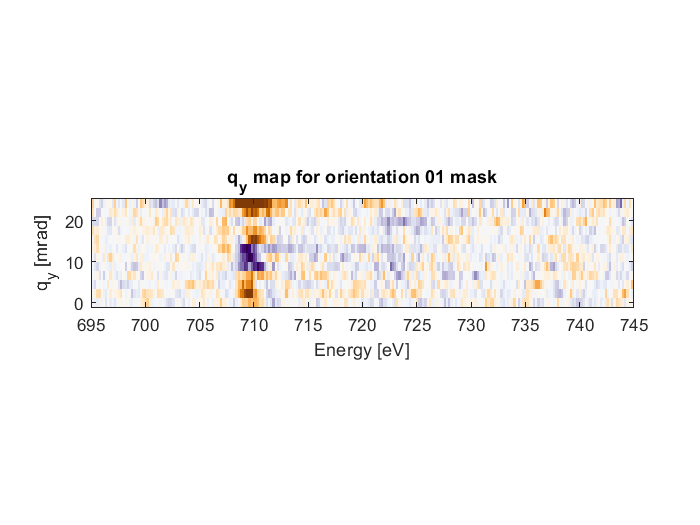

LineEELS.orient1 = fStruct;
figure('Color', 'w');
imagesc(e3, abs(qy2(1:12)), [LineEELS.orient1.EMCD]');
pbaspect([5 1 1]);
set(gca, 'YDir', 'normal');
set(gca, 'colormap', flipud(brewermap(1000, 'PuOr')));
set(gca, 'clim', [-0.04 0.04], 'xlim', [695 745]);
ylabel('q_y [mrad]');
xlabel('Energy [eV]');
title('q_y map for orientation 01 mask')

### Line profile for `mask.orient2`

win.pre = [650 700];
win.post = [730 745];

clear flm fo fStruct;
tic;
for idx = 12:-1:1
    fprintf(1, '\nIteration %02d', idx);
    tmp = q(DPEELSsum.orient2, idx);
    [fo(idx, :), mLmS(idx), fStruct(idx)] = optimMLMS(e3, ...
        tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
        'preModel', 'Power Law', ...
        'postModel', 'Linear', ...
        'SScalculation', 'Decoupled', ...
        'sigModel', 'GLmix', ...
        'xlim', [695 745], ...
        'deblur', true, ...
        'shift', true, ...
        'algorithm', 'active-set');
    close(gcf);
end


Iteration 12
Iteration 11
Iteration 10
Iteration 09
Iteration 08
Iteration 07
Iteration 06
Iteration 05
Iteration 04
Iteration 03
Iteration 02
Iteration 01

toc;

Elapsed time is 17.270889 seconds.


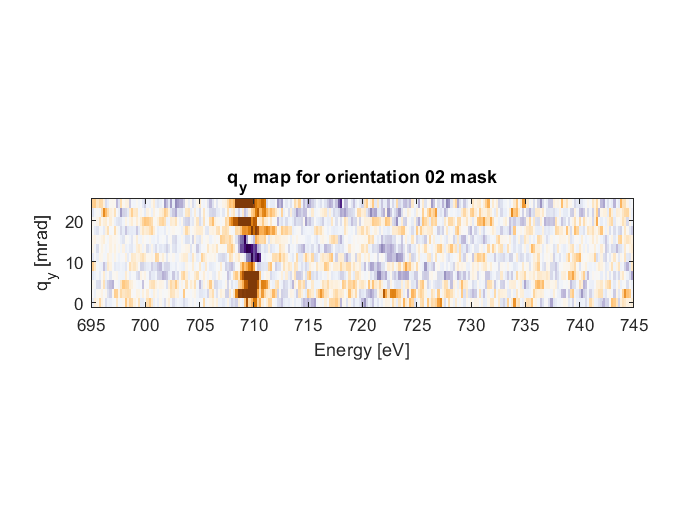

LineEELS.orient2 = fStruct;
figure('Color', 'w');
imagesc(e3, abs(qy2(1:12)), [LineEELS.orient2.EMCD]');
pbaspect([5 1 1]);
set(gca, 'YDir', 'normal');
set(gca, 'colormap', flipud(brewermap(1000, 'PuOr')));
set(gca, 'clim', [-0.04 0.04], 'xlim', [695 745]);
ylabel('q_y [mrad]');
xlabel('Energy [eV]');
title('q_y map for orientation 02 mask')

### Line profile for `mask.grain`

win.pre = [650 700];
win.post = [730 745];

clear flm fo fStruct;
tic;
for idx = 12:-1:1
    fprintf(1, '\nIteration %02d', idx);
    tmp = q(DPEELSsum.grain, idx);
    [fo(idx, :), mLmS(idx), fStruct(idx)] = optimMLMS(e3, ...
        tmp(:, 1), shift1D(sp(tmp(:, 2), -1.5), 0, true), win, ...
        'preModel', 'Power Law', ...
        'postModel', 'Linear', ...
        'SScalculation', 'Decoupled', ...
        'sigModel', 'GLmix', ...
        'xlim', [695 745], ...
        'deblur', true, ...
        'shift', true, ...
        'algorithm', 'active-set');
    close(gcf);
end


Iteration 12
Iteration 11
Iteration 10
Iteration 09
Iteration 08
Iteration 07
Iteration 06
Iteration 05
Iteration 04
Iteration 03
Iteration 02
Iteration 01

toc;

Elapsed time is 15.452193 seconds.


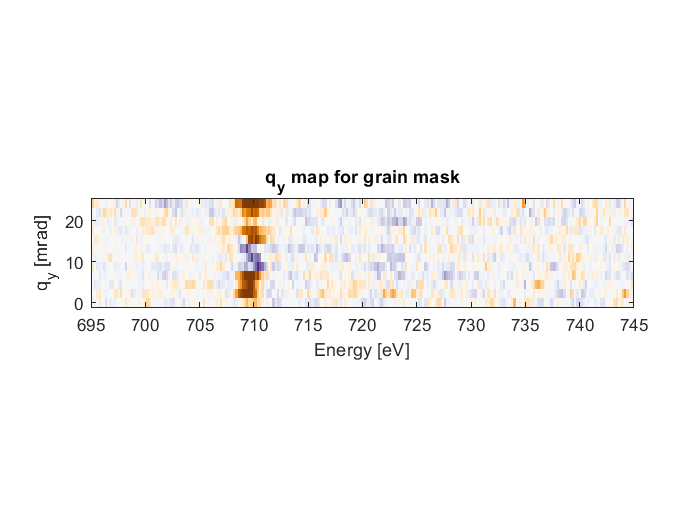

LineEELS.grain = fStruct;
figure('Color', 'w');
imagesc(e3, abs(qy2(1:12)), [LineEELS.grain.EMCD]');
pbaspect([5 1 1]);
set(gca, 'YDir', 'normal');
set(gca, 'colormap', flipud(brewermap(1000, 'PuOr')));
set(gca, 'clim', [-0.04 0.04], 'xlim', [695 745]);
ylabel('q_y [mrad]');
xlabel('Energy [eV]');
title('q_y map for grain mask')